[~,p] = fit_logistic(time_E,OD)

p =   371.2773    1.1416    0.0106


t = 0:1200;
q = p(2)./(1+exp(-p(3)*(t-p(1))));
b = bar(time_E, smell, 'y')

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 1 0]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [0 23.0000 44.0000 458.0000 468.0000 479.0000 490.0000 502.0000 859.0000 872.0000 884.0000 896.0000 908.0000 921.0000 1.0790e+03 1112 1.1240e+03]
        YData: [0.6667 0.6667 0 2 2 1.3333 1 0.6667 0.3333 0.3333 0.3333 0.6667 0.6667 0.3333 1 1 1]

  Show all properties


hold on
plot(t,q,'k');
plot(time_E, OD,'*','MarkerSize', 5,'MarkerEdgeColor','red');
xlabel('Time (min)')    
ylabel('OD600')
s=findobj('tag', 'legend')

s =   0×0 empty GraphicsPlaceholder array.


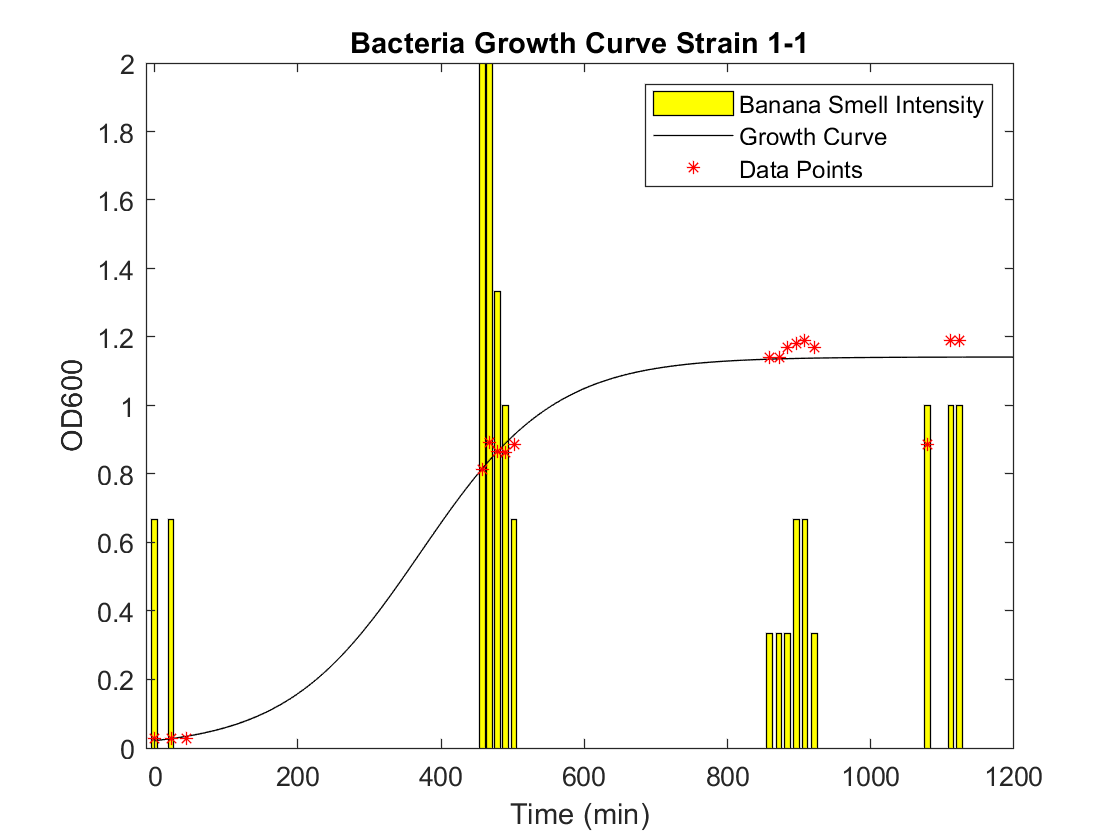


title('Bacteria Growth Curve Strain 1-1')

legend('Banana Smell Intensity','Growth Curve', 'Data Points')